# 2D Systems of equations: Row picture

Every of the equations represent a line in 2D,


$$x - 2y = 0\\
x + y = 3$$


We can reconstruct the line by given values for x and use the equation for calculating y and viceversa.

For example, for eq1:

x = 3

x = 3

y = x/2

y = 1.5000

or

y = 3

y = 3

x = 2*y;

For a bunch of point you can get a segment of the line:

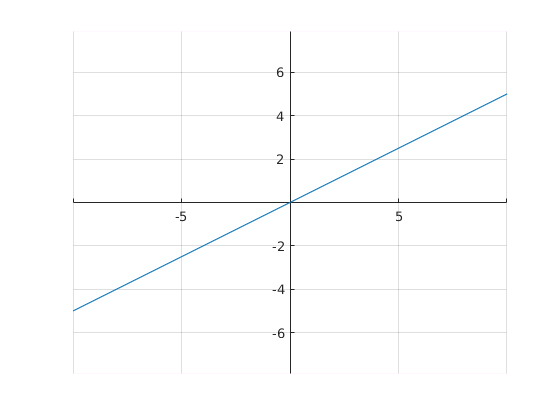

x = -10:10;
y = x/2;
plot(x,y)
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.Box = 'off';
axis equal;
grid on;

The same happens for the second equation:

x = 1

x = 1

y = 3-x

y = 2

or

y = 2

y = 2

x = 3-y

x = 1

And we can draw the line

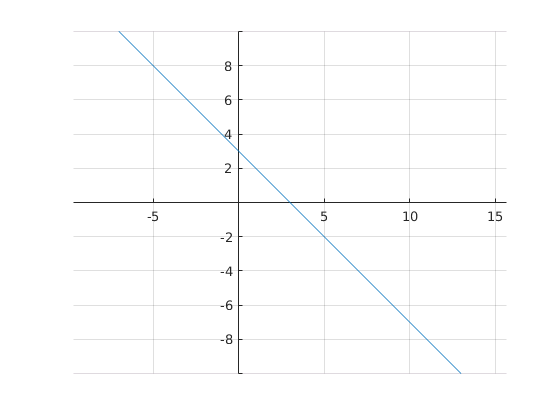

y = -10:10;
x = 3-y;
plot(x,y)
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.Box = 'off';
axis equal;
grid on;

We are interested in the points that fulfill both equations, it is the points shared by the two lines.

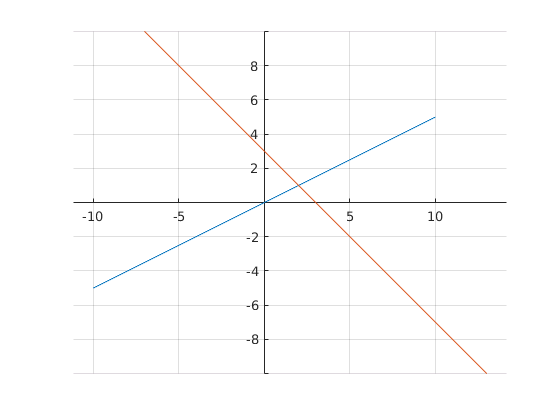

x1 = -10:10;
y1 = x1/2;

y2 = -10:10;
x2 = (3-y2);

plot(x1,y1,x2,y2)
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.Box = 'off';
axis equal;
grid on;

The spolution of the system can be found on the plot as


$$x = 2\\
y = 1$$


# Systems of equations: Column picture

The same system of equations 


$$x - 2y = 0\\
x + y = 3$$


can be thinked as a vectorial equation


$$x\big($$
 
$$1\\ 1$$
 
$$\big) + y \big($$
 
$$-2\\
\,\,\,\,\,\, 1$$
 
$$\big) = \big($$
 
$$0\\3$$
 
$$\big)$$


if we tink in ($
1\\1$) and ($-2\\ \,\,\,\,\,\,\,1$) as vectors the problem is solved by finding the values of $x
$ and $y$ such that the linear combination of the two past vectorsequals the right hand side.

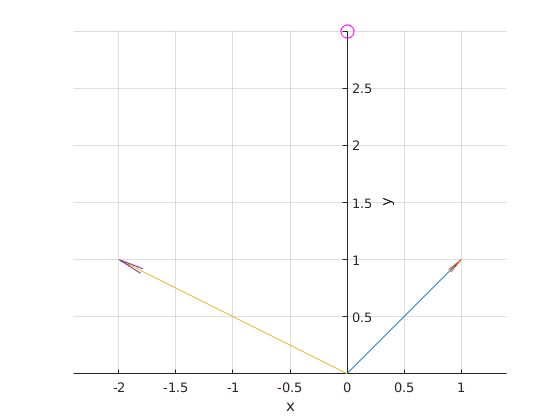

figure;
vectarrow([0;0],[1;1]);
hold on;
vectarrow([0;0],[-2;1]);
hold on;
plot(0,3,'o','MarkerSize',10,'Color','m')
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.Box = 'off';
axis equal;
grid on;

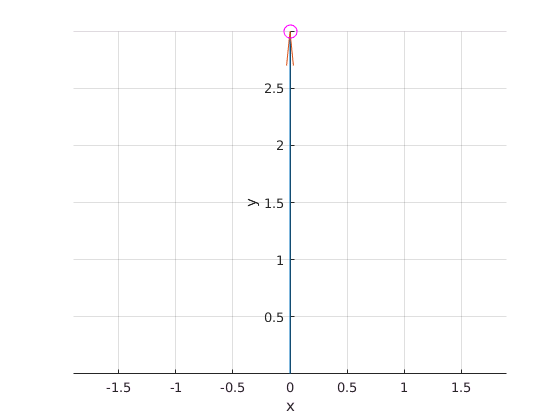


figure;
vectarrow([0;0],2*[1;1]+[-2;1]);
hold on;
plot(0,3,'o','MarkerSize',10,'Color','m');
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.Box = 'off';
axis equal;
grid on;

# 3D systems of equations: Row picture.


$$x+y+z = 3\\
x-y = 0 \\
x + z = 1$$


In the 3D case, every equation in the system represents the equation of a plane.

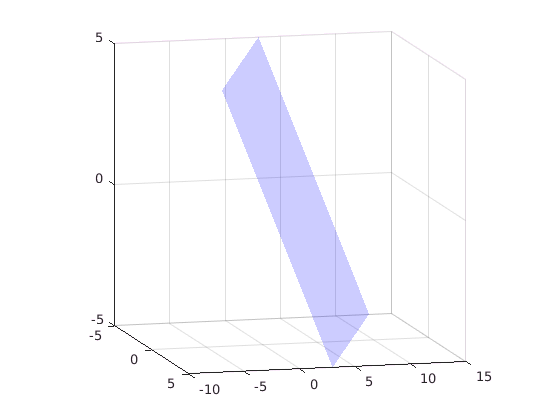

figure;
[x, z] = meshgrid(-5:0.5:5);  
yv = @(x,z) 3-x-z;
surf(x,yv(x,z),z,'FaceAlpha',0.2,'EdgeAlpha',0.2,...
    'LineStyle','none',...
    'FaceColor','b');

view(gca,[75 10]);
grid(gca,'on');
axis(gca,'square');
hold on;
axis square;

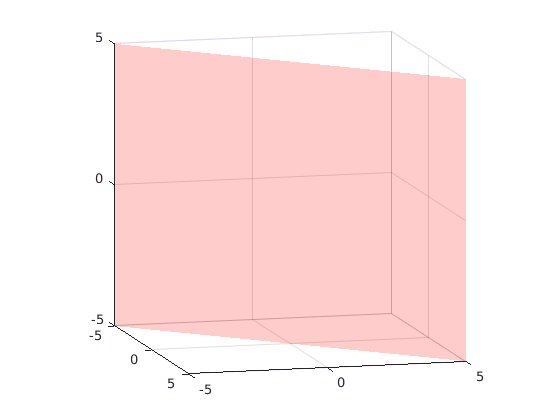

figure;

[x, z] = meshgrid(-5:0.5:5);  
yv = @(x) x;
surf(x,yv(x),z,'FaceAlpha',0.2,'EdgeAlpha',0.2,...
    'LineStyle','none',...
    'FaceColor','r');

view(gca,[75 10]);
grid(gca,'on');
axis(gca,'square');
hold on;
axis square;

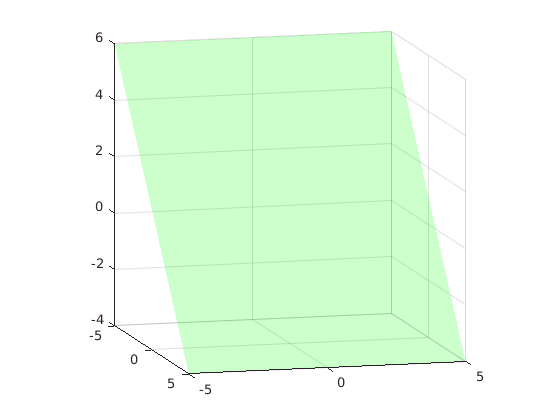

figure;

[x, y] = meshgrid(-5:0.5:5);  
zv = @(x) 1-x;
surf(x,y,zv(x),'FaceAlpha',0.2,'EdgeAlpha',0.2,...
    'LineStyle','none',...
    'FaceColor','g');

view(gca,[75 10]);
grid(gca,'on');
axis(gca,'square');
hold on;
axis square;

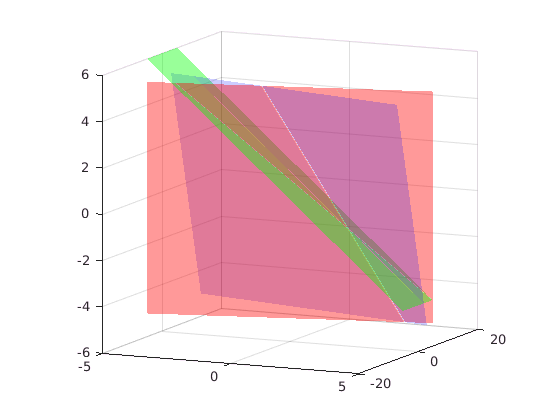

figure;
hold on;
[x, z] = meshgrid(-5:0.5:5);  
yv = @(x,z) 3-x-z;
surf(x,yv(x,z),z,'FaceAlpha',0.2,'EdgeAlpha',0.2,...
    'LineStyle','none',...
    'FaceColor','b');

[x, z] = meshgrid(-5:0.5:5);  
yv = @(x) x;
surf(x,yv(x),z,'FaceAlpha',0.4,'EdgeAlpha',0.4,...
    'LineStyle','none',...
    'FaceColor','r');

[x, y] = meshgrid(-5:0.5:5);  
zv = @(x) 1-x;
surf(x,y,zv(x),'FaceAlpha',0.4,'EdgeAlpha',0.4,...
    'LineStyle','none',...
    'FaceColor','g');

view(gca,[25 10]);
grid(gca,'on');
axis(gca,'square');
axis square;

# 3D system of equations: Column picture


$$x+y+z = 3\\
x-y = 0 \\
x+ z = 1$$


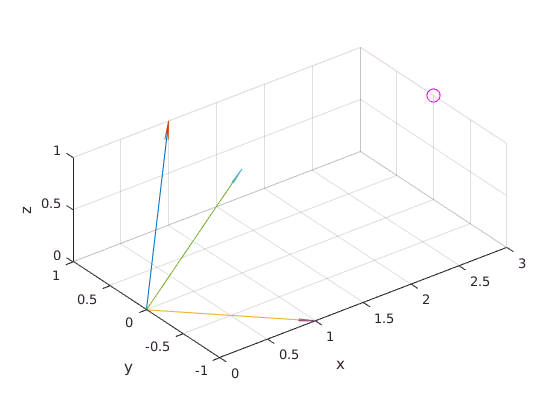

figure;
vectarrow([0;0;0],[1;1;1]);
hold on;
vectarrow([0;0;0],[1;-1;0]);
hold on;
vectarrow([0;0;0],[1;0;1]);
hold on;
plot3(3,0,1,'o','MarkerSize',10,'Color','m')
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.Box = 'off';
axis equal;
grid on;figure;

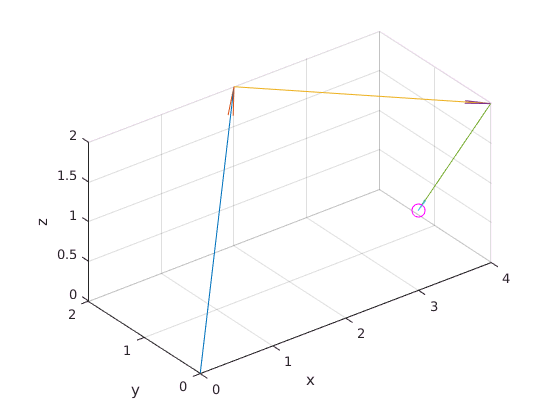

vectarrow([0;0;0],2*[1;1;1]);
hold on;
vectarrow(2*[1;1;1],2*[1;1;1]+2*[1;-1;0]);
hold on;
vectarrow(2*[1;1;1]+2*[1;-1;0],2*[1;1;1]+2*[1;-1;0]-1*[1;0;1]);
hold on;
plot3(3,0,1,'o','MarkerSize',10,'Color','m')
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.Box = 'off';
axis equal;